Textfile = load("STM32Output.txt")

Textfile =     0.0800
    0.0700
    0.0900
    0.0400
    0.0900
    0.0900
    0.0400
    0.1200
    0.0800
    0.1000


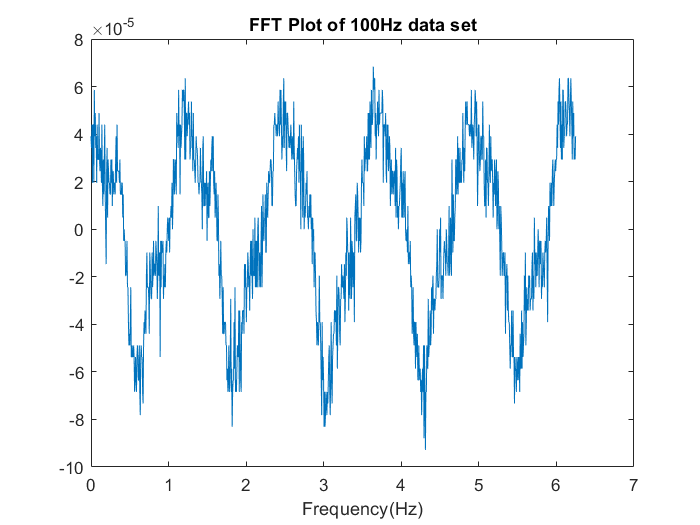

writematrix(Textfile, "STM32Output.csv");
FFTData = readtable("STM32Output.csv");


N =  2048 - 1; 
FFTData = FFTData{:, 1}/N; %data is symmetric, *2 to account for contribution of other half 
fs = 12.5;
frequency = fs*(0:(N/2))/N;

plot(frequency(1:1024), FFTData(1:1024)); %only plotting the real side of the dataset 
title("FFT Plot of 100Hz data set");
xlabel("Frequency(Hz)");